# Ecuaciones diferenciales de orden superior

Resolver ecuaciones diferenciales de segundo orden:


$$y'' + 2y' + y = 0;$$
      
$$y(0) = 5,$$
      
$$y'(0) = -3;$$


syms y(t) t

dy = diff(y, t);
d2y = diff(y, t, 2);

y0 = 5;
dy0 = -3;

y(t) = dsolve(d2y == -2*dy - y ...
    , y(0) == y0 ...
    , dy(0) == dy0)

$$y(t) = {\mathrm{e}}^{-t}\,\left(2\,t+5\right)$$

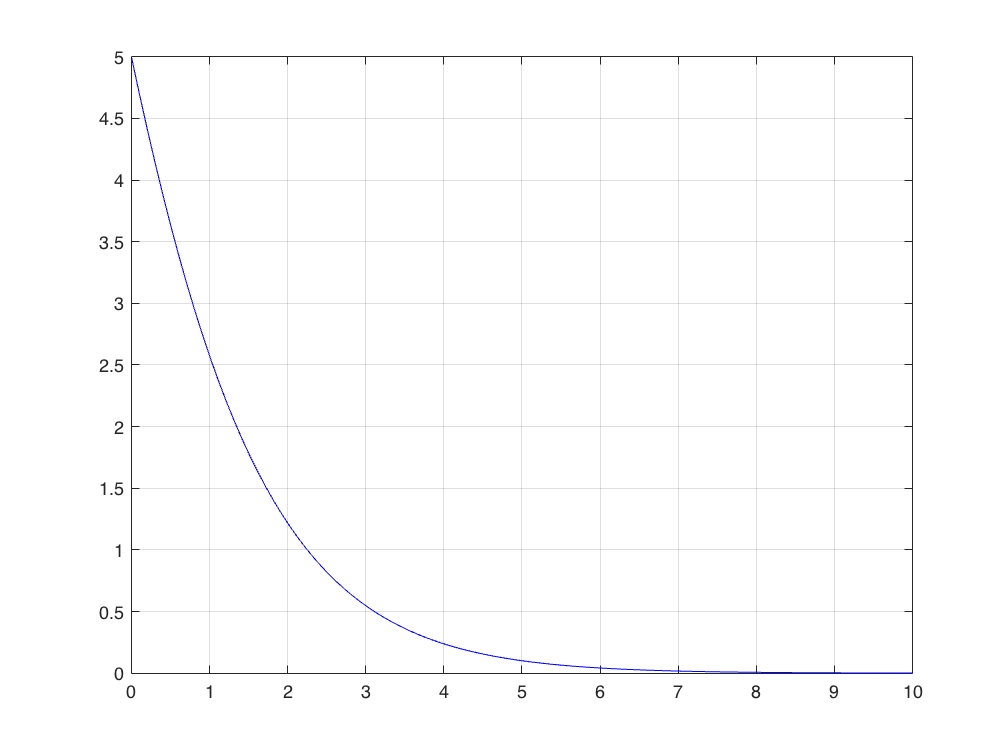


tt = linspace(0, 10);
yy = y(tt);

plot(tt, yy, 'b');
grid on;

También se puede modelar un sistema masa resorte amortiguado:


$$m\frac{d^2 }{\mathrm{d}t^2 }x+b\frac{d}{\mathrm{d}t}x+kx=f$$



$$\ddot{x} =\frac{1}{m}f-\frac{b}{m}\dot{x} -\frac{k}{m}x$$


syms x(t) t

f = t;
m = 0.5;
b = 0.01;
k = 0.05;

x0 = 0;
dx0 = 1;

dx = diff(x, t);
d2x = diff(x, t, 2);

x(t) = dsolve(d2x == (1/m)*f - (b/m)*dx - (k/m)*x, x(0) == x0, dx(0) == dx0);

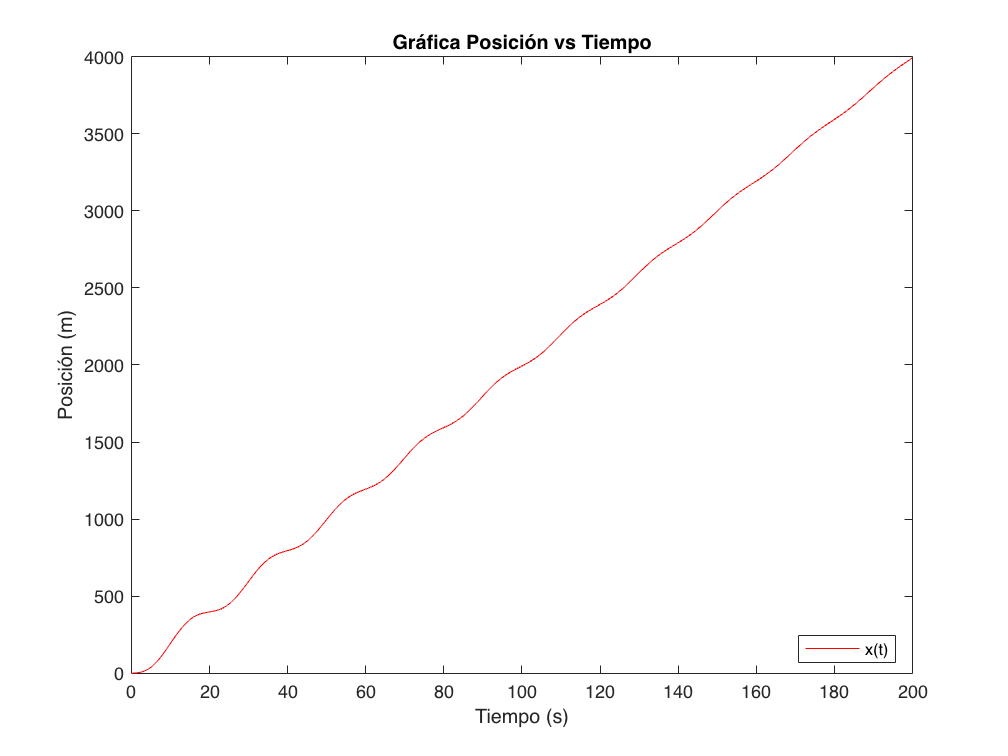

tt = linspace(0, 200, 2000);
xx = x(tt);

plot(tt, xx, 'r')
title('Gráfica Posición vs Tiempo')
legend('x(t)', 'Location', 'best')
xlabel('Tiempo (s)')
ylabel('Posición (m)')

# Sistemas de ecuaciones diferenciales ordinarias de primer orden


$$x^{\prime } =2x+4y$$



$$y^{\prime } =-x+6y$$



$$x\left(0\right)=-1\;\;\;\;\;y\left(0\right)=6$$


syms t x(t) y(t)

dx = diff(x, t);
dy = diff(y, t);

x0 = -1;
y0 = +6;

S = dsolve(dx==2*x+4*y, dy==-x+6*y, x(0)==x0, y(0)==y0);

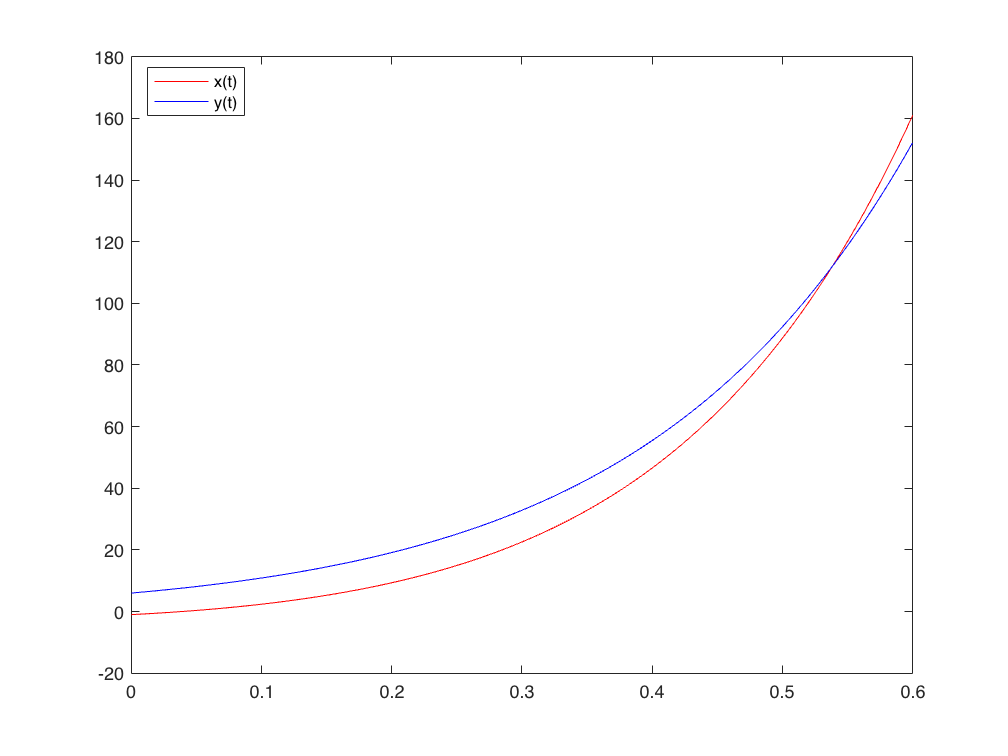

x(t) = S.x;
y(t) = S.y;

tt = linspace(0, 0.6);
xx = x(tt);
yy = y(tt);

plot(tt, xx, 'r', tt, yy, 'b');
legend('x(t)', 'y(t)', 'Location','best')